# MVO-31: LAB02 - Q2

Considerações iniciais:

- Limite de altura: $300\,m$;

- Altitude operacional: $1500\,ft = 457.2\,m$;

- Velocidade máxima: $270\,kt = 138.9\,m/s$

- $n_{max} = 5g$;

- Fator de carga constante na recuperação;

- Ângulo de lançamento: $-25°$.

2a)


$$n_z = \cos(\gamma) + \frac{v^2}{rg}$$
 
$$\rightarrow$$

$$r(\gamma) = \frac{v^2}{g(n_z - \cos(\gamma))}$$


2b)

O raio de recuperação crítico é obtido quando utiliza-se o valor de $n_z = 5$ na expressão encontrada acima, pois um raio menor implicaria um fator de carga maior do que o limite do ensaio.

2c)

Sistema de EDOs do movimento:


$$\dot{x} = v\cdot\sin{\gamma}$$



$$\dot{y} = v\cdot\cos{\gamma}$$



$$\dot{\gamma} = \frac{v}{r(\gamma)} = \frac{g(n_z - \cos(\gamma))}{v}$$


Condições iniciais:


$$x_0 = 0$$



$$y_0 = 1500$$



$$\gamma_0 = -25°$$


Gerando o gráfico pedido pelo enunciado para uma velocidade constante e igual à velocidade máxima de $138.9\,m/s$:

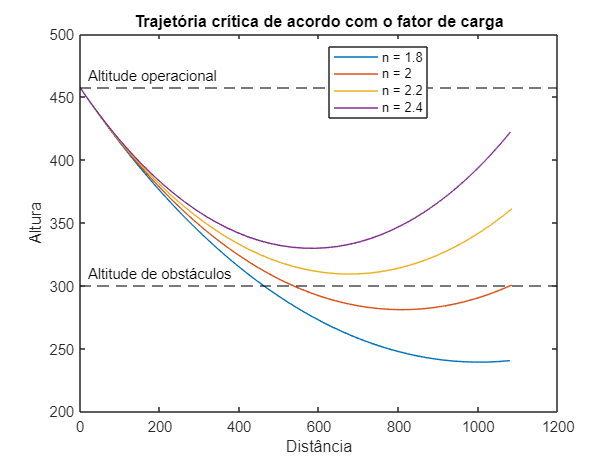

range = 1.6 + 0.2*[1:4];
for n = range
    f2 = @(t, pos)fun(t, pos, n);
    [t, pos] = ode45(f2,[0 8],[0 457.2 -deg2rad(25)]);
    
    plot(pos(:,1),pos(:,2))
    hold on
end
yline(300,'k--')
text(20,310,'Altitude de obstáculos')
yline(457.2,'k--')
text(20,467.2,'Altitude operacional')
ylim([200,500])
legs = [string("n = " + range) '' ''];
legend(legs,"Location","best")
ylabel("Altura")
xlabel("Distância")
title("Trajetória crítica de acordo com o fator de carga")
hold off

2d)

O fator de carga máximo $n_{max}$ para essa manobra ser segura é tal que a altitude mínima seja de $300\,m$: 

for n = linspace(2,2.2,1000)
    f2 = @(t, pos)fun(t, pos, n);
    [t, pos] = ode45(f2,[0 8],[0 457.2 -deg2rad(25)]);
    if abs(min(pos(:,2)) - 300) < 0.01
        n
    end
end

n = 2.1271

function pos_P = fun(~, pos, n)
    g = 9.8; v = 138.9;
    gamma = pos(3);
    pos_P = [v.*cos(gamma) v.*sin(gamma) g*(n-cos(gamma))/v]';
end